%% PROJECT 1: COMPLETE F1 OPTIMIZATION (Dynamic + Setup + Racing Line)
% Auteurs: [Ton Nom]
% Date: 2025
% Description: Optimisation trajectoire et setup pour F1 sur circuit GeoJSON.

clear; close all; clc;

%% 1. PARAMÈTRES GLOBAUX & CONFIGURATION
% ---------------------------------------------------------
circuit_file = fullfile(pwd, 'Circuits_Data', 'de-1927.geojson'); % <-- TON FICHIER ICI
track_width = 10; % Largeur de piste pour l'optimisation trajectoire (m)

% --- Paramètres Véhicule Fixes ---
car.m = 750;           % Masse (kg)
car.L = 3.4;           % Empattement
car.lf = 1.8; car.lr = 1.6;
car.h_cg = 0.30;       % Hauteur CG
car.P_max = 750000;    % Puissance (W)
car.F_max = 16000;     % Traction Max (N)
car.F_brake_max = 30000;
car.rho = 1.225; 
car.Area = 1.5;
car.Cd = 0.9;          % Drag Coefficient
car.Cl = 3.5;          % Downforce Coefficient Total
car.mu_x = 1.7;        % Grip Longi
car.mu_y = 1.6;        % Grip Lat
car.C_alpha_f = 120000; % Rigidité Pneu Av
car.C_alpha_r = 180000; % Rigidité Pneu Arr

%% 2. PARTIE A : OPTIMISATION DU SETUP (Sensitivity Analysis)
% On cherche la meilleure répartition Aéro (Balance Avant/Arrière)
% Trop d'avant = Survirage (Instable). Trop d'arrière = Sous-virage (Lent).

fprintf('--- DÉBUT DE L''OPTIMISATION SETUP (Aero Balance) ---\n');

--- DÉBUT DE L'OPTIMISATION SETUP (Aero Balance) ---



% Plage de test : de 40% à 50% sur l'avant
bal_range = 0.40 : 0.01 : 0.50; 
lap_times = zeros(size(bal_range));
min_speeds = zeros(size(bal_range));

% Boucle d'optimisation
for k = 1:length(bal_range)
    current_bal = bal_range(k);
    
    % Lancer la simulation complète (sans graphiques pour aller vite)
    [T_lap, ~, ~] = Run_F1_Simulation(circuit_file, track_width, car, current_bal, false);
    
    lap_times(k) = T_lap;
    fprintf('Test Balance %.0f%% Front -> Temps : %.3f s\n', current_bal*100, T_lap);
end

Test Balance 40% Front -> Temps : 105.602 s
Test Balance 41% Front -> Temps : 105.454 s
Test Balance 42% Front -> Temps : 105.294 s
Test Balance 43% Front -> Temps : 105.123 s
Test Balance 44% Front -> Temps : 104.979 s
Test Balance 45% Front -> Temps : 104.831 s
Test Balance 46% Front -> Temps : 104.681 s
Test Balance 47% Front -> Temps : 104.569 s
Test Balance 48% Front -> Temps : 104.815 s
Test Balance 49% Front -> Temps : 105.120 s
Test Balance 50% Front -> Temps : 105.413 s



% Trouver le meilleur setup
[best_time, idx_best] = min(lap_times);
best_bal = bal_range(idx_best);

fprintf('\n>>> MEILLEUR SETUP TROUVÉ : %.1f%% Aéro sur l''avant.\n', best_bal*100);


>>> MEILLEUR SETUP TROUVÉ : 47.0% Aéro sur l'avant.


fprintf('>>> Gain par rapport au pire setup : %.3f s\n', max(lap_times) - best_time);

>>> Gain par rapport au pire setup : 1.033 s


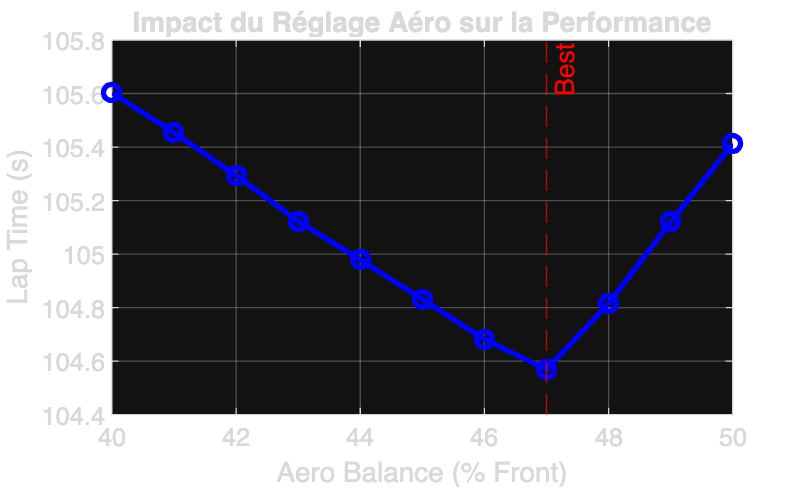


% Afficher la courbe d'optimisation
figure('Name', 'Setup Optimization', 'Color', 'w');
plot(bal_range*100, lap_times, 'b-o', 'LineWidth', 2);
xlabel('Aero Balance (% Front)'); ylabel('Lap Time (s)');
title('Impact du Réglage Aéro sur la Performance');
grid on; xline(best_bal*100, 'r--', 'Best');


%% 3. PARTIE B : SIMULATION FINALE & VISUALISATION (Best Setup)
% On relance la simu avec le meilleur paramètre et on affiche TOUT.

fprintf('\n--- LANCEMENT DE LA SIMULATION DÉTAILLÉE (Best Setup) ---\n');


--- LANCEMENT DE LA SIMULATION DÉTAILLÉE (Best Setup) ---


[T_final, SimData, TrackData] = Run_F1_Simulation(circuit_file, track_width, car, best_bal, true);

   -> Optimisation Trajectoire (50 itér.)...


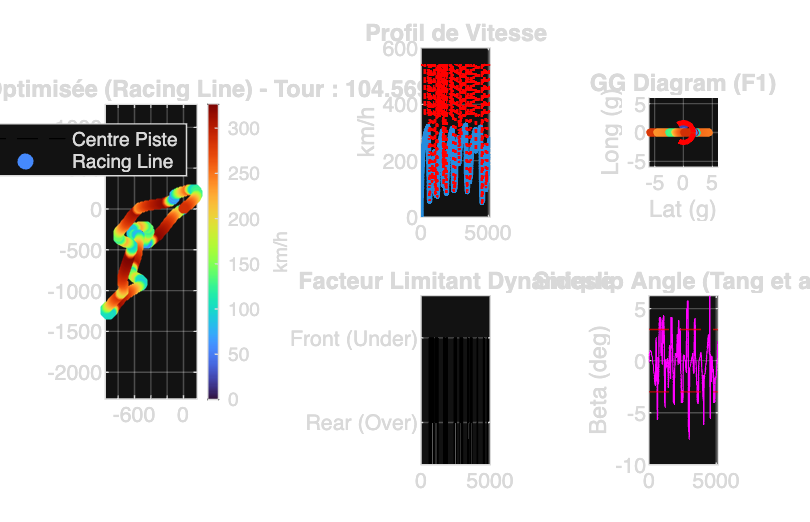


% --- VISUALISATION DES RÉSULTATS ---
figure('Name', 'F1 Dynamic Analysis', 'Color', 'w', 'Position', [50 50 1400 900]);

% 1. Carte avec Trajectoire Optimisée vs Centre
subplot(2,3,[1 4]);
plot(TrackData.x_center, TrackData.y_center, 'k--', 'LineWidth', 0.5); hold on;
scatter(TrackData.x_opt, TrackData.y_opt, 15, SimData.v*3.6, 'filled');
colormap turbo; c=colorbar; c.Label.String='km/h';
title(['Trajectoire Optimisée (Racing Line) - Tour : ' num2str(T_final, '%.3f') 's']);
axis equal; grid on; legend('Centre Piste', 'Racing Line');

% 2. Profil Vitesse & Limites
subplot(2,3,2);
plot(SimData.S, SimData.v*3.6, 'LineWidth', 2); hold on;
plot(SimData.S, SimData.v_limit*3.6, 'r:', 'LineWidth', 1);
ylabel('km/h'); title('Profil de Vitesse'); grid on; xlim([0 SimData.S(end)]);

% 3. Facteur Limitant (Sous-virage vs Sur-virage)
subplot(2,3,5);
area(SimData.S, SimData.limiter, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'k'); 
yticks([1 2]); yticklabels({'Rear (Over)', 'Front (Under)'});
title('Facteur Limitant Dynamique'); ylim([0.5 2.5]); grid on;

% 4. GG Diagram (Élargi)
subplot(2,3,3);
acc_long = diff([0 SimData.v]).^2 ./ (2*2.0); % Approx ds=2
acc_long(diff([0 SimData.v])<0) = -acc_long(diff([0 SimData.v])<0);
acc_lat = SimData.v.^2 .* SimData.k;
scatter(acc_lat/9.81, acc_long/9.81, 10, SimData.v*3.6, 'filled');
hold on;
th=0:0.1:2*pi; plot(car.mu_x*cos(th), car.mu_x*sin(th), 'r--', 'LineWidth', 2);
xlabel('Lat (g)'); ylabel('Long (g)'); title('GG Diagram (F1)');
axis equal; grid on; xlim([-6 6]); ylim([-6 6]);

% 5. Sideslip Estimation
subplot(2,3,6);
plot(SimData.S, SimData.beta, 'm');
yline([3 -3], 'r--');
ylabel('Beta (deg)'); title('Sideslip Angle (Tang et al.)'); grid on;



%% ========================================================================
%% FONCTION PRINCIPALE DE SIMULATION (Moteur Physique)
%% ========================================================================
function [T_total, SimData, TrackData] = Run_F1_Simulation(filename, track_w, car, aero_bal, do_print)

    ds = 2.0; % Pas de discrétisation

    % --- 1. CHARGEMENT & TRAITEMENT PISTE ---
    try
        jsonText = fileread(filename); data = jsondecode(jsonText);
        if isfield(data,'features'), raw=data.features(1).geometry.coordinates; else, raw=data.geometry.coordinates; end
        lon=raw(:,1); lat=raw(:,2);
    catch
        % Fallback si pas de fichier (Cercle test)
        th = linspace(0, 2*pi, 500)'; 
        lon = cos(th); lat = sin(th); 
        if do_print, disp('Warning: Fichier non trouvé, utilisation cercle test.'); end
    end

    % Conv. Mètres
    R = 6371000; lat0=lat(1); lon0=lon(1);
    x_raw = R*deg2rad(lon-lon0)*cos(deg2rad(lat0));
    y_raw = R*deg2rad(lat-lat0);
    
    % Nettoyage doublons
    d2=diff(x_raw).^2+diff(y_raw).^2; is_mov=[true; d2>1e-5];
    x_c=x_raw(is_mov); y_c=y_raw(is_mov);
    % Fermeture boucle
    if norm([x_c(1)-x_c(end), y_c(1)-y_c(end)]) > 5
        x_c(end+1) = x_c(1); y_c(end+1) = y_c(1);
    end
    
    % Interpolation Spline (Centre de piste)
    dist_s = sqrt(diff(x_c).^2+diff(y_c).^2); t_raw = [0; cumsum(dist_s)];
    S_query = 0:ds:t_raw(end);
    x_center = spline(t_raw, x_c, S_query);
    y_center = spline(t_raw, y_c, S_query);
    
    % --- 2. OPTIMISATION TRAJECTOIRE (Racing Line Heuristic) ---
    % Algorithme "Apex Cutting" : On déplace les points vers l'intérieur
    x_opt = x_center; y_opt = y_center;
    N = length(x_opt);
    alpha = 0.15; % Taux de lissage
    iterations = 50; % Nb passes
    
    if do_print, fprintf('   -> Optimisation Trajectoire (%d itér.)...\n', iterations); end
    
    for k=1:iterations
        for i=2:N-1
            % Milieu géométrique
            xm = (x_opt(i-1)+x_opt(i+1))/2;
            ym = (y_opt(i-1)+y_opt(i+1))/2;
            
            % Vecteur déplacement (Lissage)
            xn = (1-alpha)*x_opt(i) + alpha*xm;
            yn = (1-alpha)*y_opt(i) + alpha*ym;
            
            % Contrainte Largeur Piste
            dist = sqrt((xn - x_center(i))^2 + (yn - y_center(i))^2);
            if dist < track_w/2
                x_opt(i) = xn; y_opt(i) = yn;
            end
        end
        % Gestion boucle fermée (Start = End)
        x_opt(1) = x_opt(N); y_opt(1) = y_opt(N);
    end
    
    % --- 3. CALCUL COURBURE (Sur trajectoire optimisée) ---
    dx=Gradient(x_opt,ds); dy=Gradient(y_opt,ds);
    ddx=Gradient(dx,ds); ddy=Gradient(dy,ds);
    curvature = (dx.*ddy - dy.*ddx) ./ (dx.^2 + dy.^2).^(1.5);
    % Filtre
    curvature(abs(curvature)>0.25) = 0.25*sign(curvature(abs(curvature)>0.25));
    curvature(isnan(curvature)) = 0;
    
    % --- 4. MODELE DYNAMIQUE (Calcul V_Limit) ---
    v_limit = zeros(1,N);
    limiter = zeros(1,N); % 1=Rear, 2=Front
    g = 9.81;
    
    for i=1:N
        k_val = abs(curvature(i));
        if k_val < 1e-4, v_limit(i) = 360/3.6; continue; end
        
        % Recherche dichotomique de la vitesse max d'équilibre
        v_low=0; v_high=150;
        for iter=1:10
            v_t = (v_low+v_high)/2;
            
            % Aero Forces
            Fz_tot = 0.5*car.rho*car.Area*car.Cl*v_t^2;
            Fz_f = (car.m*g*car.lr/car.L) + Fz_tot*aero_bal;
            Fz_r = (car.m*g*car.lf/car.L) + Fz_tot*(1-aero_bal);
            
            % Grip Max
            Fy_f_max = car.mu_y * Fz_f;
            Fy_r_max = car.mu_y * Fz_r;
            
            % Demande Centrifuge
            F_centri = car.m * v_t^2 * k_val;
            Fy_f_req = F_centri * car.lr/car.L;
            Fy_r_req = F_centri * car.lf/car.L;
            
            % Check Stabilité
            if Fy_f_req <= Fy_f_max && Fy_r_req <= Fy_r_max
                v_low = v_t;
            else
                v_high = v_t;
                if Fy_r_req > Fy_r_max, limiter(i)=1; else, limiter(i)=2; end
            end
        end
        v_limit(i) = v_low;
    end
    
    % --- 5. INTÉGRATION LONGITUDINALE (Forward-Backward) ---
    v_fwd = zeros(1,N);
    v_bwd = zeros(1,N); v_bwd(end) = v_limit(end);
    
    % Forward
    for i=1:N-1
        v = max(v_fwd(i), 5);
        F_drag = 0.5*car.rho*car.Area*car.Cd*v^2;
        
        % Grip Arrière dispo pour traction (Cercle friction arrière)
        Fz_tot = 0.5*car.rho*car.Area*car.Cl*v^2;
        % Transfert charge approx (m*1g*h/L)
        load_transfer = (car.m*9.81*car.h_cg)/car.L; 
        Fz_r = (car.m*g*car.lf/car.L) + Fz_tot*(1-aero_bal) + load_transfer;
        
        F_lat_r = (car.m*v^2*abs(curvature(i))) * (car.lf/car.L);
        F_grip_r = car.mu_x * Fz_r;
        
        if F_lat_r >= F_grip_r, F_tract=0; else, F_tract=sqrt(F_grip_r^2 - F_lat_r^2); end
        
        F_eng = min(car.F_max, car.P_max/v);
        F_net = min(F_eng, F_tract) - F_drag;
        
        v_next = sqrt(v_fwd(i)^2 + 2*(F_net/car.m)*ds);
        v_fwd(i+1) = min(v_next, v_limit(i+1));
    end
    
    % Backward
    for i=N:-1:2
        v = max(v_bwd(i), 5);
        F_drag = 0.5*car.rho*car.Area*car.Cd*v^2;
        
        % Grip Global Freinage
        Fz_tot = car.m*g + 0.5*car.rho*car.Area*car.Cl*v^2;
        F_grip_tot = car.mu_x * Fz_tot;
        F_lat_tot = car.m*v^2*abs(curvature(i));
        
        if F_lat_tot >= F_grip_tot, F_brake_avail=0; else, F_brake_avail=sqrt(F_grip_tot^2 - F_lat_tot^2); end
        
        F_net = min(car.F_brake_max, F_brake_avail) + F_drag;
        
        v_prev = sqrt(v_bwd(i)^2 + 2*(F_net/car.m)*ds);
        v_bwd(i-1) = min(v_prev, v_limit(i-1));
    end
    
    v_final = min(v_fwd, v_bwd);
    T_total = sum(ds ./ max(v_final, 1));
    
    % --- 6. CALCUL SIDESLIP & DATA OUTPUT ---
    yaw_rate = v_final .* curvature;
    % Eq 15 Approx Tang et al.
    K1 = (car.m * car.lf) / (car.L * car.C_alpha_r);
    K2 = car.lr / car.L;
    beta = (K1 .* v_final .* yaw_rate + K2 .* curvature * car.lf) * (180/pi);
    
    % Structuration des données
    SimData.S = S_query; SimData.v = v_final; SimData.v_limit = v_limit;
    SimData.k = curvature; SimData.limiter = limiter; SimData.beta = beta;
    TrackData.x_center = x_center; TrackData.y_center = y_center;
    TrackData.x_opt = x_opt; TrackData.y_opt = y_opt;

end

function d=Gradient(f,ds), n=length(f); d=zeros(size(f)); d(1)=(f(2)-f(1))/ds; d(n)=(f(n)-f(n-1))/ds; d(2:n-1)=(f(3:n)-f(1:n-2))/(2*ds); end